## Thermal Model of a brick kiln

### **Define constants and Initial Conditions**

clear all;
close all;
clc;
%constants
c_brick=900; %specific heat of bricks, [j/(kgK)], 
k_brick=0.03; %thermal conductivity of bricks, [W/mm/K],
alpha_out=15/1000000; %convective heat transfer, [W/mm2/K],
e_brick=0.901; %brick emissivity, []
T_ambient=25; %Ambient temperature, C
totalfuel=19.2*1000000*4000; %[j] Based on lower heating value of wood and wood mass
brick_density=1600E-9; %[kg/mm³]
firing_area=13*1000000; % mm² 
c=0.65; %scaling s for heat flow

### **Set parameters: geometry, video, fuel addition**

kiln_version="solidkiln_long";
create_video=true;
optimize_fuel=false;

### Temperature development within burning chambers

Read and plot the temperature profile to be used to scale the heat flow into the burning chambers

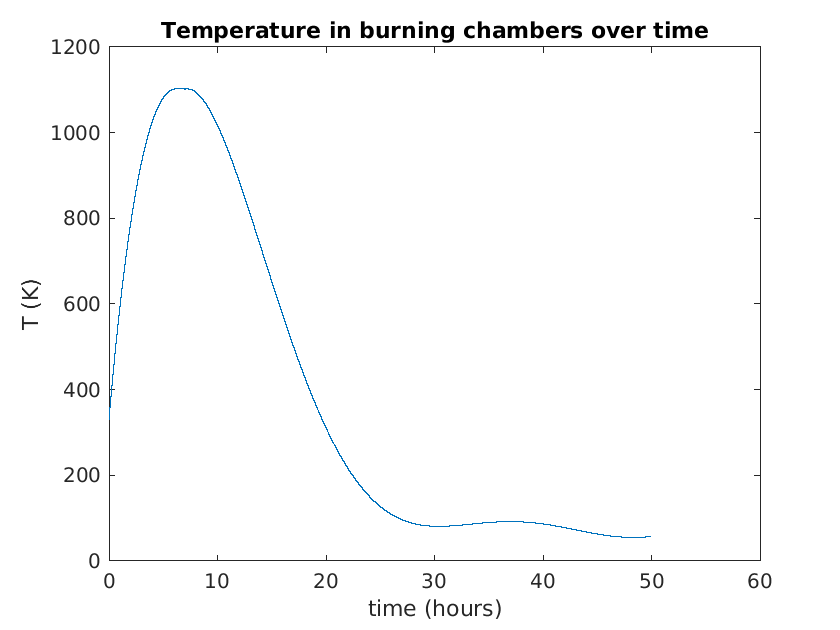


temperature=csvread("high_heat_profiles/interpolated.csv");
t1=temperature(1:7*3600);
t_fill=temperature(7*3600:8*3600);

t_fill(1:end)=max(temperature);
t2=temperature(7*3600:end);
temperature=[t1;t_fill;t2];
temperature=temperature(1*3600:51*3600);
temperature=(1.1*temperature).';

totaltime = length(temperature);
time = linspace(1,totaltime,length(temperature));
figure
plot(time/3600, temperature)
xlabel('time (hours)')
ylabel('T (K)')
title('Temperature in burning chambers over time')

### Import and plot model, create mesh for FEM

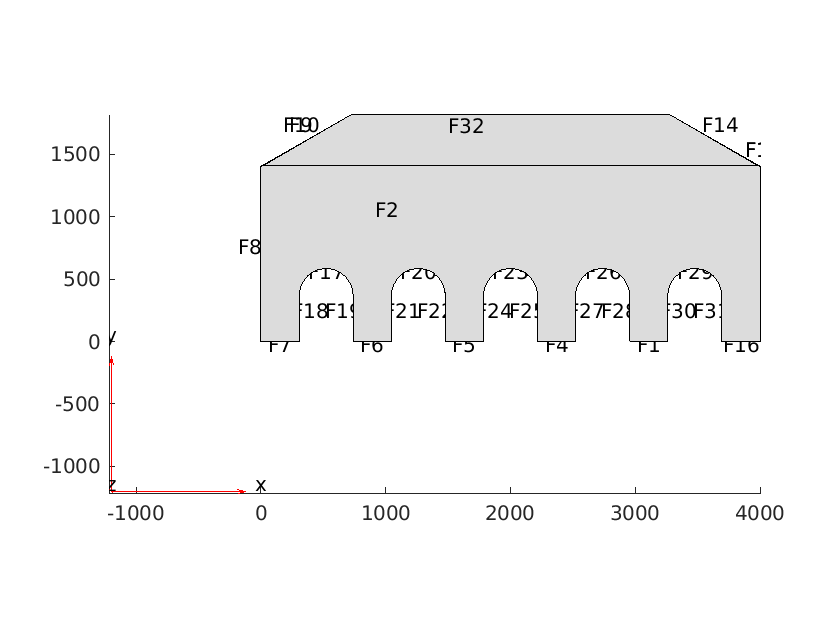

model = createpde("thermal", "transient");
kiln_path = "models/"+kiln_version+".stl";
gm = importGeometry(model, kiln_path);
pdegplot(model,"FaceLabels","on");
view([-0 90])

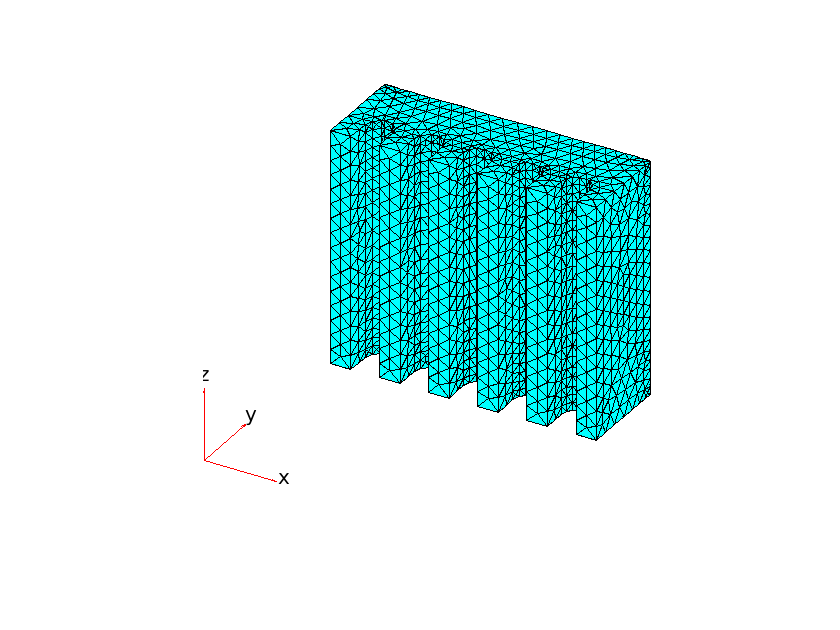

generateMesh(model);
pdemesh(model);

kiln_volume=volume(model.Mesh);
kiln_mass=kiln_volume*brick_density;

### Set properties and boundary conditions 

tlist = linspace(1, length(temperature));

%Assuming that heat flow into trenches is proportional to temperature in
%firing chambers, calculate that scaling s for one timestep
sumT=sum(temperature);
scale_heatflow=totalfuel/sumT/firing_area*c;
if optimize_fuel==true
    scale_center=0.75;
    scale_offcenter=0.75;
else
    scale_center=1;
    scale_offcenter=1;
end

thermalProperties(model,"ThermalConductivity",k_brick, ...
                               "MassDensity",brick_density, ...
                               "SpecificHeat",c_brick);
model.StefanBoltzmannConstant = 5.670373E-14;
conv = @(location, state) convBC(location, state, temperature);

if(kiln_version=="solidkiln_new")
    trench_length=2500;
    thermalBC(model,"Face", [8,9,12,14, 31, 32], "AmbientTemperature", T_ambient,"ConvectionCoefficient",alpha_out,"Emissivity",e_brick);
    thermalBC(model,"Face", [2,3], "AmbientTemperature", T_ambient,"ConvectionCoefficient",20/1000000,"Emissivity",e_brick);
    flux = @(location, state) heatflow(location, state, temperature, scale_heatflow, trench_length);
    %flux2 = @(location, state) heatflow(location, state, temperature, scale_heatflow*0.5, trench_length);
    thermalIC(model,T_ambient);
    thermalBC(model,"Face",[16,19,22,25,28],"HeatFlux",flux); 
    %thermalBC(model,"Face",[17, 18, 20, 21, 23, 24, 26, 27, 29, 30],"HeatFlux",flux2);
end
if(kiln_version=="solidkiln_wide")
    trench_length=2500;
    thermalBC(model,"Face", [12, 38, 29,30, 11, 36], "AmbientTemperature", T_ambient,"ConvectionCoefficient",alpha_out,"Emissivity",e_brick);
    thermalBC(model,"Face", [2,3], "AmbientTemperature", T_ambient,"ConvectionCoefficient",20/1000000,"Emissivity",e_brick);
    flux_center = @(location, state) heatflow(location, state, temperature, scale_heatflow*scale_center, trench_length);
    flux_offcenter = @(location, state) heatflow(location, state, temperature, scale_heatflow*scale_offcenter, trench_length);
    flux_side = @(location, state) heatflow(location, state, temperature, scale_heatflow, trench_length);
    thermalIC(model,T_ambient);
    thermalBC(model,"Face",[14, 40],"HeatFlux",flux_center); 
    thermalBC(model,"Face",[23,20, 17,43, 46,49],"HeatFlux",flux_offcenter); 
    thermalBC(model,"Face",[26, 52],"HeatFlux",flux_side);
end
if(kiln_version=="solidkiln_long")
    trench_length=3500;
    thermalBC(model,"Face", [8,9,10,12,14, 15, 32, 33], "AmbientTemperature", T_ambient,"ConvectionCoefficient",alpha_out,"Emissivity",e_brick);
    thermalBC(model,"Face", [2,3], "AmbientTemperature", T_ambient,"ConvectionCoefficient",20/1000000,"Emissivity",e_brick);
    flux = @(location, state) heatflow(location, state, temperature, scale_heatflow, trench_length);
    thermalIC(model,T_ambient);
    thermalBC(model,"Face",[17,20,23,26,29],"HeatFlux",flux); 
end
if(kiln_version=="solidkiln_longwide")
    trench_length=3500;
    thermalBC(model,"Face", [12,38, 30, 29, 36 11, 37], "AmbientTemperature", T_ambient,"ConvectionCoefficient",alpha_out,"Emissivity",e_brick); 
    thermalBC(model,"Face", [2,3], "AmbientTemperature", T_ambient,"ConvectionCoefficient",20/1000000,"Emissivity",e_brick);
    flux_center = @(location, state) heatflow(location, state, temperature, scale_heatflow*scale_center, trench_length);
    flux_offcenter = @(location, state) heatflow(location, state, temperature, scale_heatflow*scale_offcenter, trench_length);
    flux_side = @(location, state) heatflow(location, state, temperature, scale_heatflow, trench_length);
    thermalIC(model,T_ambient);
    thermalBC(model,"Face",[14, 40],"HeatFlux",flux_center); 
    thermalBC(model,"Face",[23,20, 17,43, 46,49],"HeatFlux",flux_offcenter); 
    thermalBC(model,"Face",[26, 52],"HeatFlux",flux_side);
end
if(kiln_version=="solidkiln_longwidehigh")
    trench_length=3500;
    thermalBC(model,"Face", [38,11,12,37,36,29,30], "AmbientTemperature", T_ambient,"ConvectionCoefficient",alpha_out,"Emissivity",e_brick); 
    thermalBC(model,"Face", [2,3], "AmbientTemperature", T_ambient,"ConvectionCoefficient",20/1000000,"Emissivity",e_brick);
    flux_center = @(location, state) heatflow(location, state, temperature, scale_heatflow*scale_center, trench_length);
    flux_offcenter = @(location, state) heatflow(location, state, temperature, scale_heatflow*scale_offcenter, trench_length);
    flux_side = @(location, state) heatflow(location, state, temperature, scale_heatflow, trench_length);
    thermalIC(model,T_ambient);
    thermalBC(model,"Face",[14, 40],"HeatFlux",flux_center); 
    thermalBC(model,"Face",[23,20, 17,43, 46,49],"HeatFlux",flux_offcenter); 
    thermalBC(model,"Face",[26, 52],"HeatFlux",flux_side);
end

### Solve PDE 

result = solve(model, tlist);
T = result.Temperature;
if optimize_fuel==true
    kiln_version=kiln_version+'_optimized';
end

### Plot and write to video

video_name = "solidkiln_long.avi"

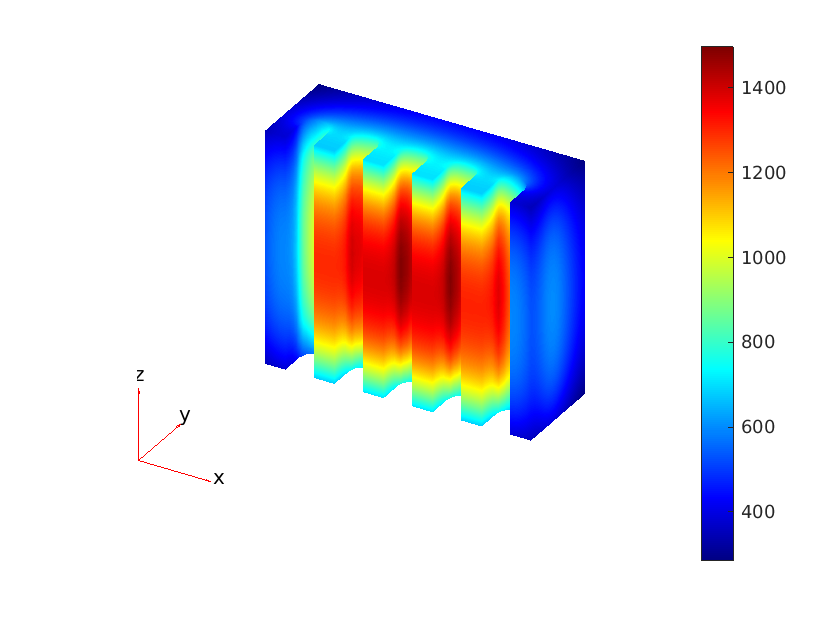

if create_video==true
    T_max=max(max(T));
    T_min=min(min(T));
        for i = 1:100
        pdeplot3D(model,"ColorMapData", T(:,i));
        timedispl = duration(seconds(tlist(i)),'format','hh:mm');
        title(['Time: ', char(timedispl)])
        caxis([T_min, T_max]);
          F(i) = getframe(gcf);
          view([-0 90])
          drawnow
        end
      % create the video writer with 1 fps
      video_name=kiln_version+'.avi'
      writerObj = VideoWriter(video_name);
      writerObj.FrameRate = 10;
      % set the seconds per image
    
    % open the video writer
    open(writerObj);
    % write the frames to the video
    for i=1:length(F)
        % convert the image to a frame
        frame = F(i) ;   
        view([-0 90])
        writeVideo(writerObj, frame);
    end
    % close the writer object
    close(writerObj);
    pdeplot3D(model, "ColorMapData", T(:,28))
end

### Evaluate heat flow at all positions

v = linspace(-0.5,0.5,11);
times = [1:100];
s = 10;

p2 = interpolateTemperature(result,163*s, 164*s, 125*s, times);
p3 = interpolateTemperature(result,126*s, 70*s, 125*s, times);
p4 = interpolateTemperature(result,90*s, 112*s,125*s,  times);
p5 = interpolateTemperature(result,90*s, 159*s,125*s,  times);
p6 = interpolateTemperature(result,53*s, 60*s,125*s,  times);
p7 = interpolateTemperature(result,163*s, 112*s,125*s,  times);
p8 = interpolateTemperature(result,35*s, 126*s,126*s,  times);
p9 = interpolateTemperature(result,200*s, 70*s, 12*s, times);
p10 = interpolateTemperature(result,163*s, 112*s,12*s,  times);
p11 = interpolateTemperature(result,163*s, 135*s,12*s,  times);
p12 = interpolateTemperature(result,126*s, 70*s,12*s,  times);
p13 = interpolateTemperature(result,85*s, 112*s,12*s,  times);
p14 = interpolateTemperature(result,85*s, 140*s,12*s,  times);
p15 = interpolateTemperature(result,53*s, 70*s,12*s,  times);
p16 = interpolateTemperature(result,40*s, 126*s,12*s,  times);

times=times/100*50;

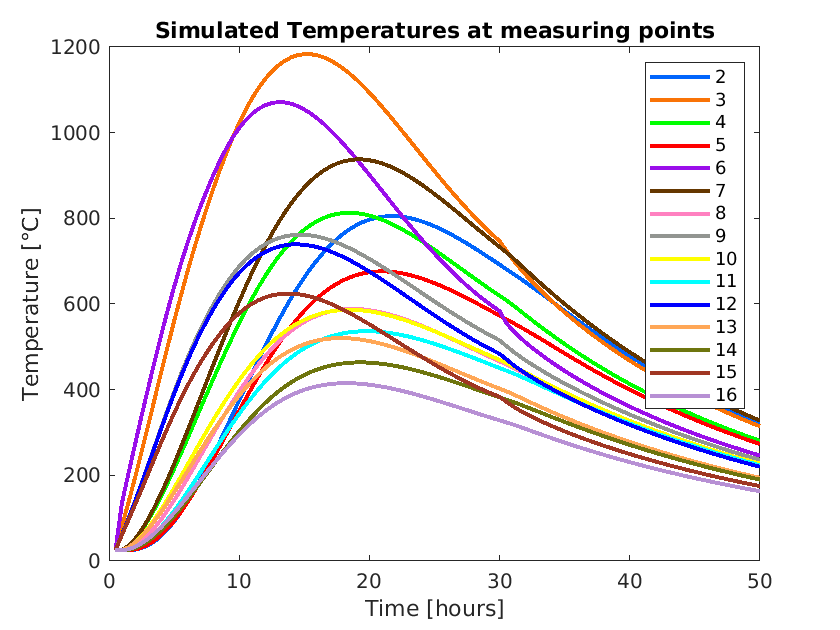



h(1) = plot(times,p2, 'LineWidth',2, 'color', '#0165fc');

title('Simulated Temperatures at measuring points')

hold on

h(2) = plot(times,p3, 'LineWidth',2, 'color', '#f97306');
h(3) = plot(times,p4, 'LineWidth',2, 'color', 'green');
h(4) = plot(times,p5, 'LineWidth',2, 'color', 'red');
h(5) = plot(times,p6, 'LineWidth',2, 'color', '#9a0eea');
h(6) = plot(times,p7, 'LineWidth',2, 'color', '#653700');
h(7) = plot(times,p8, 'LineWidth',2, 'color', '#ff81c0');
h(8) = plot(times,p9, 'LineWidth',2, 'color', '#929591');
h(9) = plot(times,p10, 'LineWidth',2, 'color', 'yellow');
h(10) = plot(times,p11, 'LineWidth',2, 'color', 'cyan');
h(11) = plot(times,p12, 'LineWidth',2, 'color', 'blue');
h(12) = plot(times,p13, 'LineWidth',2, 'color', '#ffa756');
h(13) = plot(times,p14, 'LineWidth',2, 'color', '#6e750e');
h(14) = plot(times,p15, 'LineWidth',2, 'color', '#a03623');
h(15) = plot(times,p16, 'LineWidth',2, 'color', '#b790d4');
xlabel("Time [hours]")
ylabel("Temperature [°C]")
legend(h,'2','3', '4', '5', '6', '7', '8','9', '10', '11', '12', '13', '14', '15', '16')

### Evaluate quality of firing over entire oven.

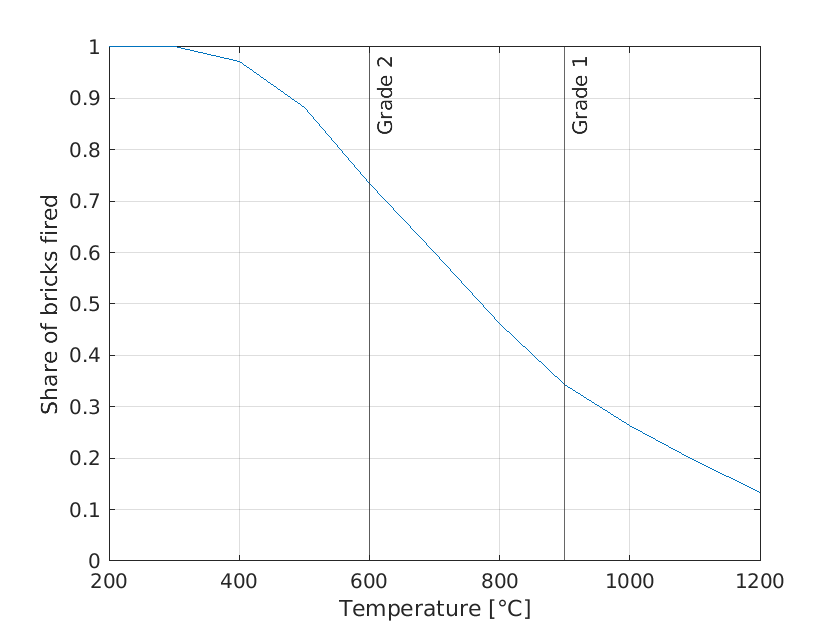


bins = [200, 300, 400, 500, 600, 700, 800, 900, 1000, 1100,1200];
hist=[];
for i = bins
    lowT =find(T<i);
    soaking = T;
    soaking(lowT)=0;
    soaking=soaking~=0;
    soaking_period=sum(soaking, 2);
    sufficient_bricks=soaking_period~=0;
    sufficient_percent=sum(sufficient_bricks)/length(T);
    hist = [hist, sufficient_percent];
    
end
figure
plot(bins, hist)
axis([200 1200 0 1])
xline(600,'-',{'Grade 2'});
xline(900,'-',{'Grade 1'});
xlabel('Temperature [°C]')
ylabel('Share of bricks fired')

grid on

### **Save variables to file**

filename = kiln_version +'.mat';
save(filename);